# Initialize

close all;
clear variables; 
global n_plot
init_FB();

### Observation bandwidth

f_min = 200e9; % lowest frequency
f_max = 460e9; % highest frequency
nF    = 1e4; %number of frequency samples
f     = linspace(f_min,f_max,nF); % frequency  

### Filter-bank properties

Qi          = Inf;%3000; %3300;%Inf; % It can be a vector
sep         = 1/4; %0.133;%0.1625;%1/4;%1/2;%3/4;
Ql_target   = 100;
ThruLineLosses = 0; 
S           = 1; % Oversampling

f0_min      = 220e9;
f0_max      = 2*f0_min;
nFilters    = floor( 1 + log10(f0_max / f0_min) / log10(1 + 1 ./ Ql_target ./ S) );

f0          = zeros(1,nFilters);
f0(1)       = f0_min;

for filter_i=2:nFilters
   f0(filter_i) = f0(filter_i-1) + f0(filter_i-1) * 1 ./ Ql_target ./ S;
end
f0 = sort(f0,'descend');

% TL-Impedances
Z0_KID      = 54.81;
Z0_thru     = 79.04;



singleFilterPlot = nFilters;

% SET SETTINGS
Settings.singleFilterPlot = nFilters; 
Settings.Z0_thru = Z0_thru;
Settings.Z0_KID = Z0_KID;
Settings.Qi = Qi;
Settings.ThruLineLosses = ThruLineLosses;
Settings.sep = sep;
Settings.f0 = f0;
Settings.Ql_target = Ql_target;

### Loop

n_loops = 5;

for iter = 1:n_loops
    n_plot = 0;



### Variances

    %% Ql %%
    Ql_sigma = 0.1; % Variance of Ql, normalized to 1
    
    %% f0 %%
    f0_sigma = 0;%0.27;% .* Ql_target ./ 500; % Relative variance of f0 (df), normalized to 1. 
    f0_drift = 0; % linear drift of f0
    f0_offset = 0; % additive offset of f0
    
    % Lower bound on Ql_scattered, based on analysis of Deshima II by Akira
    Ql_min_thresh = -1.5 .* Ql_target .* Ql_sigma;
    
    
    
    num_elem = 4; 
    Ql_variance = zeros(num_elem,nFilters);
    f0_variance = zeros(num_elem,nFilters);
    
    interFilterVariance = true;
    
    
    if interFilterVariance
        
%         Ql_sigma = Ql_sigma ./ sqrt(2);
%         f0_sigma = f0_sigma ./ sqrt(2);
    
        for i_elem = 1:num_elem %#ok<*UNRCH> 
            
            %%%% Scattered design parameters %%%%
            Ql_variance(i_elem,:) = Ql_target .* Ql_sigma .* randn(1,nFilters);
            Ql_variance(i_elem,Ql_variance(i_elem,:) < Ql_min_thresh) = Ql_min_thresh;
            df = f0 ./ Ql_target;
            f0_variance(i_elem,:) = df .* f0_sigma .* randn(1,nFilters);
        end
    else
        
        %%%% Scattered design parameters %%%%
        Ql_variance = repmat(Ql_target .* Ql_sigma .* randn(1,nFilters),4,1);
        Ql_variance(Ql_variance < Ql_min_thresh) = Ql_min_thresh;
        df = f0 ./ Ql_target;
        f0_variance = repmat(df .* f0_sigma .* randn(1,nFilters),4,1);
    end
    
    Settings.f0_variance = f0_variance;
    Settings.Ql_variance = Ql_variance;

# Filterbanks

## Directional filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceDirectionalFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 5.410802 seconds


Section took 5.059393 seconds


Section took 4.914229 seconds


Section took 4.864299 seconds


Section took 4.981686 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_dir(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.756397 seconds
Usable Spectral Fraction = 0.99
Section took 0.617436 seconds


Section took 1.477866 seconds
Usable Spectral Fraction = 0.99
Section took 0.496580 seconds


Section took 1.447313 seconds
Usable Spectral Fraction = 0.99
Section took 0.472425 seconds


Section took 1.446141 seconds
Usable Spectral Fraction = 1.00
Section took 0.497085 seconds


Section took 1.451943 seconds
Usable Spectral Fraction = 0.99
Section took 0.458501 seconds


    % % % showDimensions(f,f0,l_thru)

## Reflector filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceReflectorFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 3.279002 seconds


Section took 2.786728 seconds


Section took 2.811116 seconds


Section took 2.765018 seconds


Section took 2.877661 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_refl(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.377976 seconds
Usable Spectral Fraction = 0.98
Section took 0.493865 seconds


Section took 1.326337 seconds
Usable Spectral Fraction = 0.99
Section took 0.499593 seconds


Section took 1.348416 seconds
Usable Spectral Fraction = 0.99
Section took 0.468410 seconds


Section took 1.328358 seconds
Usable Spectral Fraction = 0.98
Section took 0.460851 seconds


Section took 1.379387 seconds
Usable Spectral Fraction = 0.99
Section took 0.504791 seconds


    % % % % showDimensions(f,f0,l_thru)

## Manifold filter

    tic;
    [ABCD_SingleToTermination,ABCD_SingleToMKID,ABCD_FilterBank,ABCD_EachFilter] = varianceManifoldFilter(f,Settings);
    elapsed_time = toc;
    fprintf('Section took %f seconds\n', elapsed_time)

Section took 2.257948 seconds


Section took 2.152193 seconds


Section took 2.163425 seconds


Section took 2.167757 seconds


Section took 2.207995 seconds


    
%     showSingleFilter(f,f0(singleFilterPlot),ABCD_SingleToTermination,ABCD_SingleToMKID,Z0_thru,Z0_KID,Ql_target)
    Data_man(iter) = calcPower(f,ABCD_FilterBank,ABCD_EachFilter,Z0_thru,Z0_KID,Ql_target);

Section took 1.376855 seconds
Usable Spectral Fraction = 0.91
Section took 0.507059 seconds


Section took 1.305505 seconds
Usable Spectral Fraction = 0.91
Section took 0.477048 seconds


Section took 1.317106 seconds
Usable Spectral Fraction = 0.89
Section took 0.495378 seconds


Section took 1.324939 seconds
Usable Spectral Fraction = 0.91
Section took 0.472931 seconds


Section took 1.468909 seconds
Usable Spectral Fraction = 0.90
Section took 0.521995 seconds


    % % showDimensions(f,f0,l_thru)
    
end

## Plotting

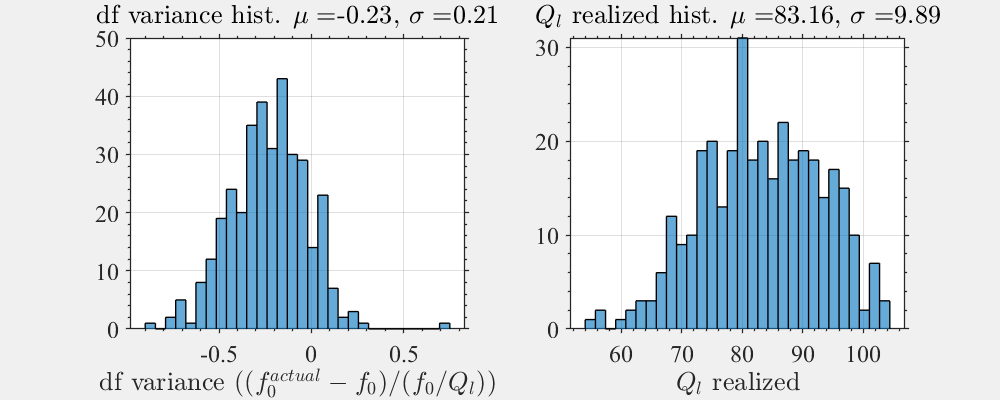

close all; 
clear functions; %#ok<CLFUNC>
n_plot = 1;
showFilterBank(f,Data_dir); 
showMetrics(f,Ql_target,Data_dir);

Stats_dir = calcStatistics(f0,Ql_target,Data_dir);
showStatistics(f,Data_dir,Stats_dir);

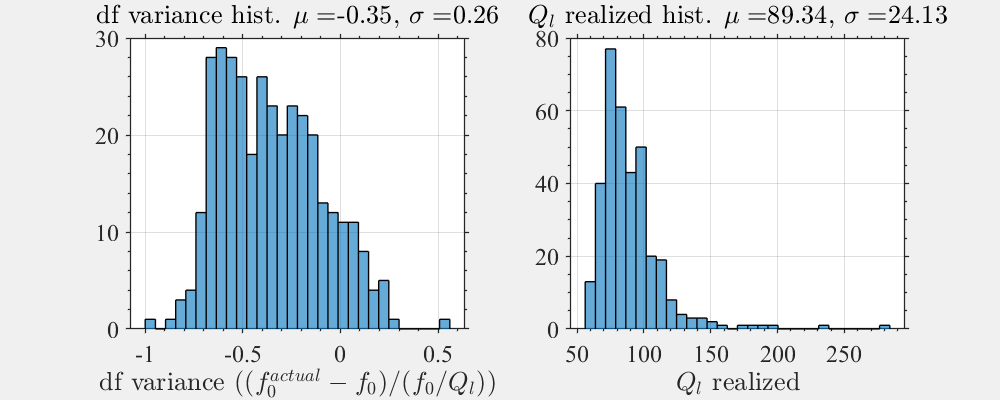


n_plot = 2;
showFilterBank(f,Data_refl);
showMetrics(f,Ql_target,Data_refl);

Stats_refl = calcStatistics(f0,Ql_target,Data_refl);
showStatistics(f,Data_refl,Stats_refl);

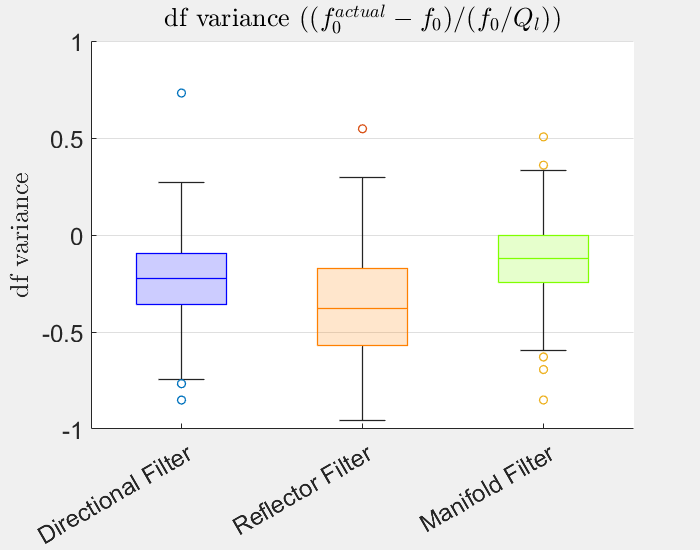

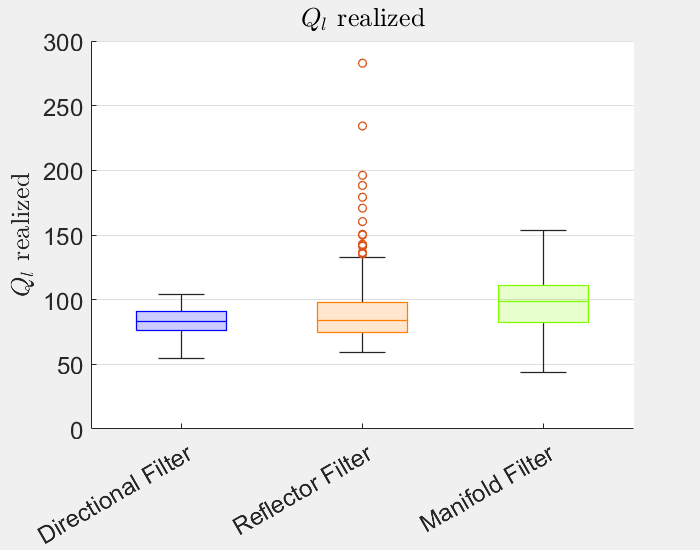

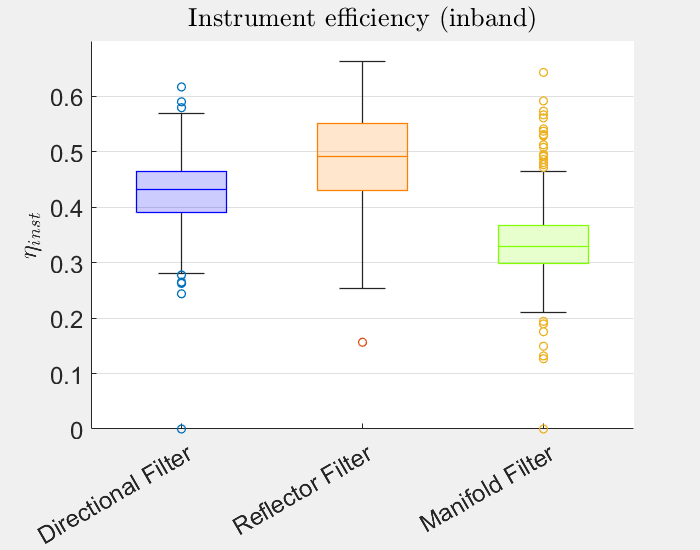

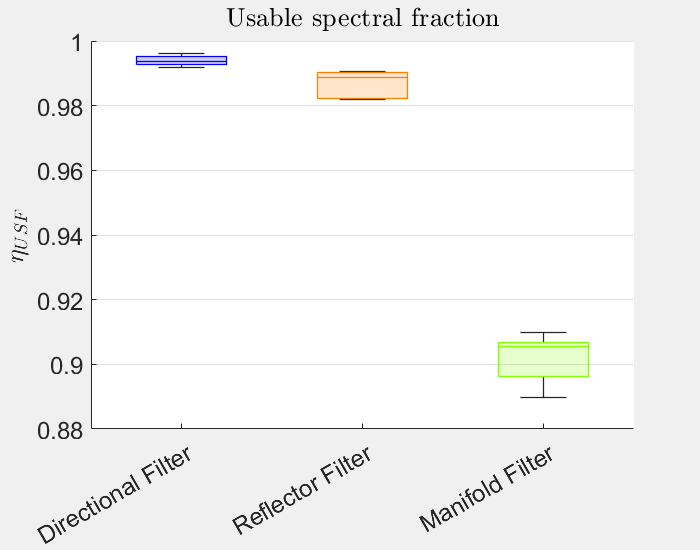

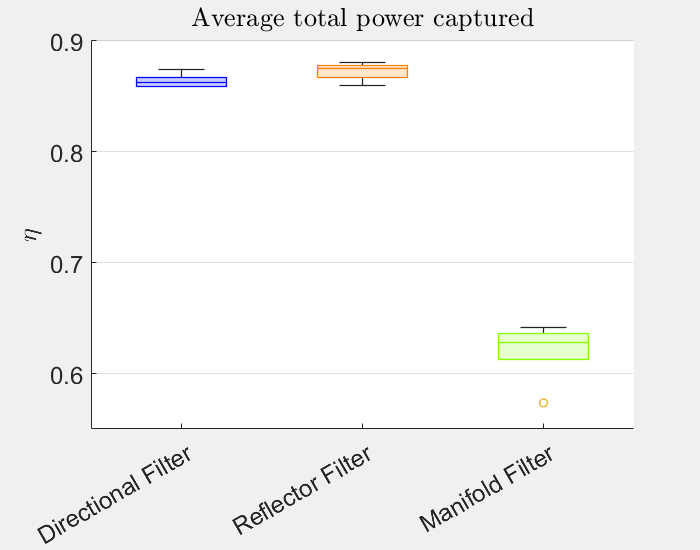

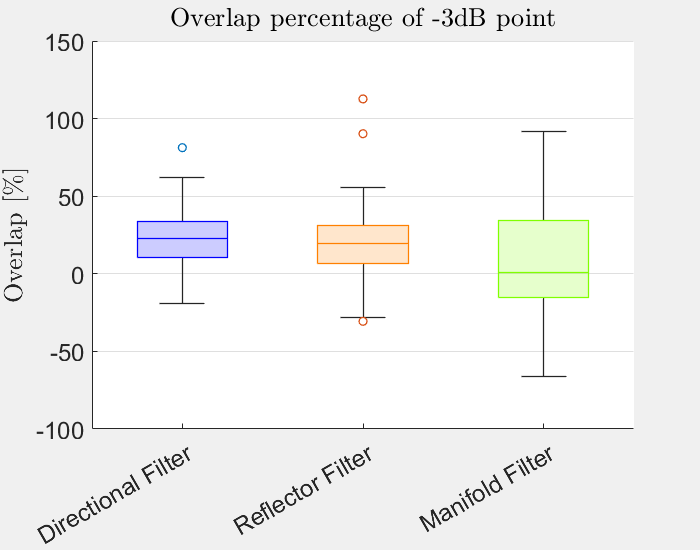

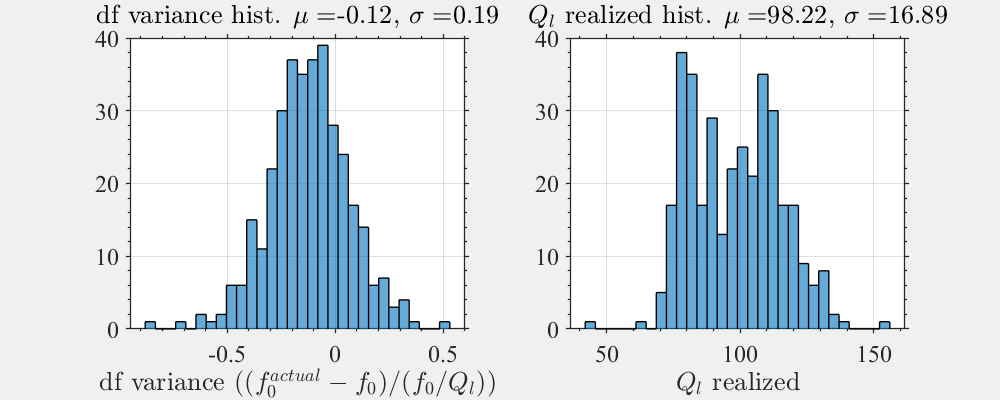



n_plot = 3;
showFilterBank(f,Data_man);
showMetrics(f,Ql_target,Data_man);

Stats_man = calcStatistics(f0,Ql_target,Data_man);
showStatistics(f,Data_man,Stats_man);

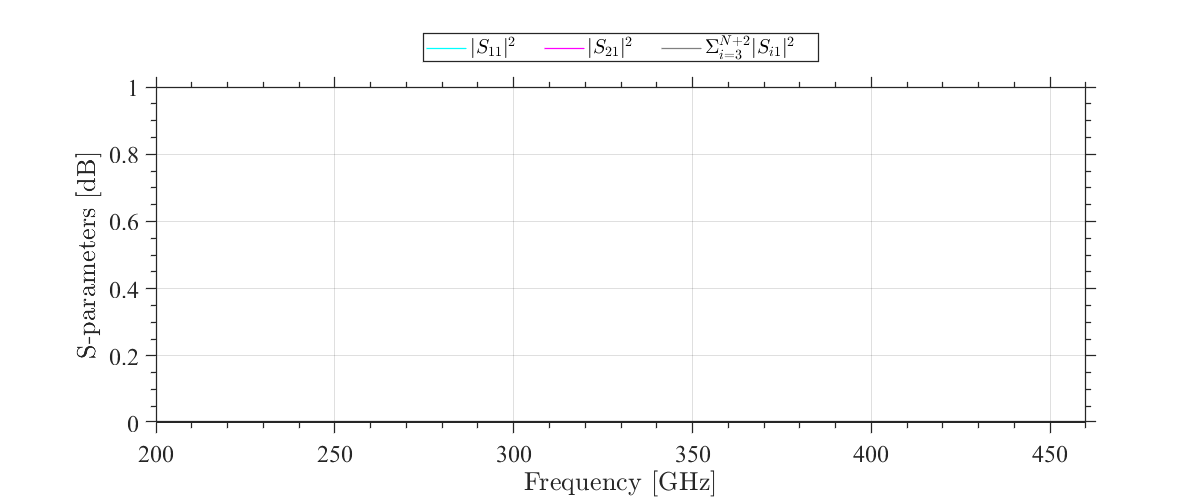

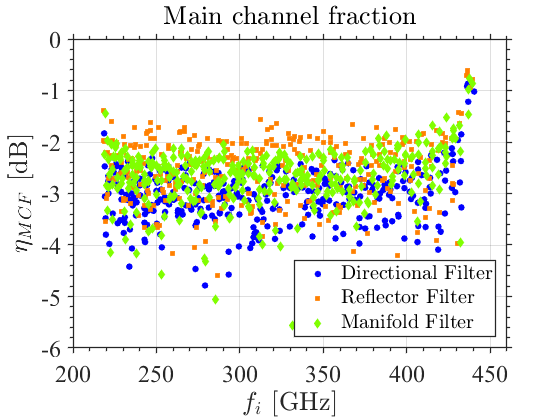

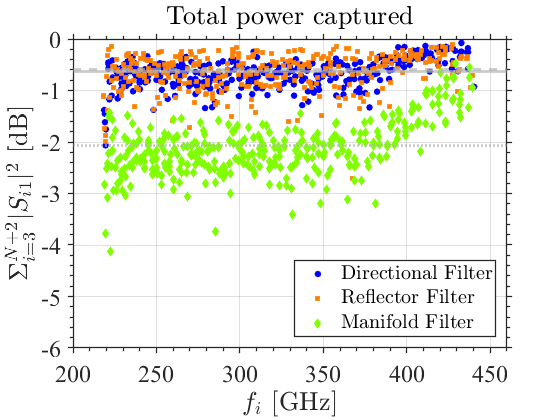

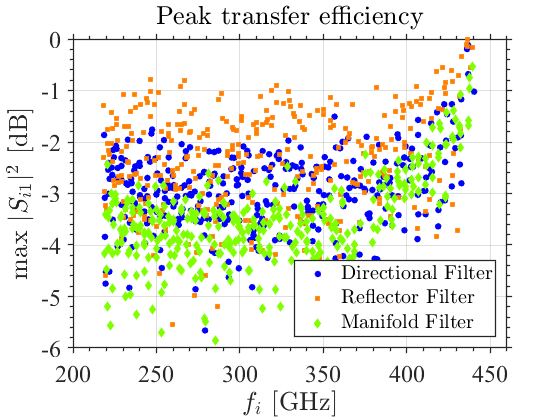

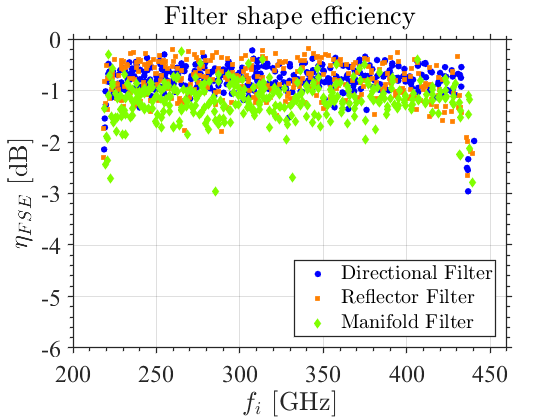

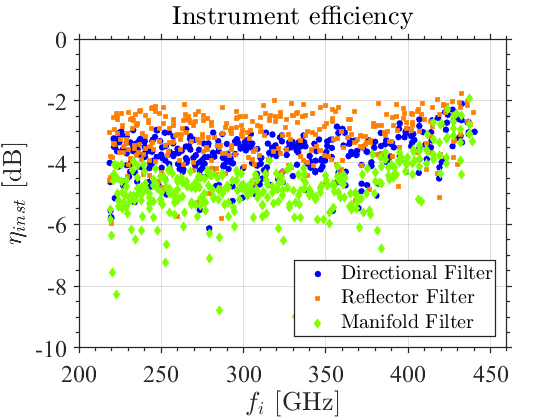

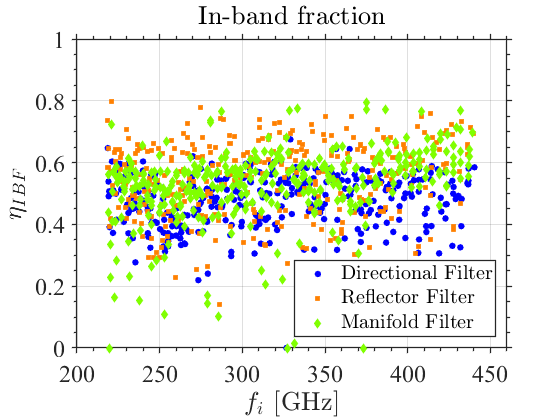

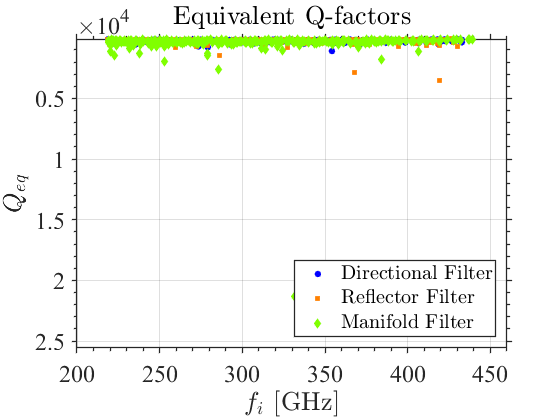



formatPlotting();